#### Euclidean Norm

load('net.mat')
load('test_data1_cell.mat');
load('test_data1.mat');

net = net;

% Setting up simulation parameters
start = 1;
numSimulations = 30;
data = test_data1_cell;
data11 = test_data1;

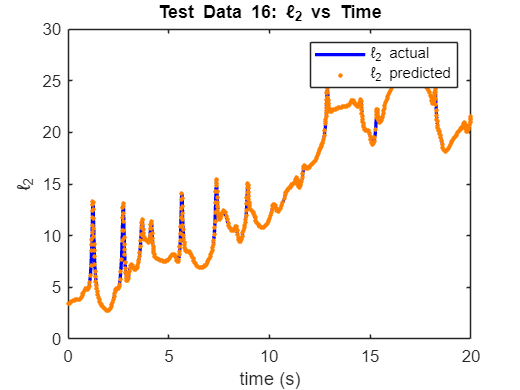

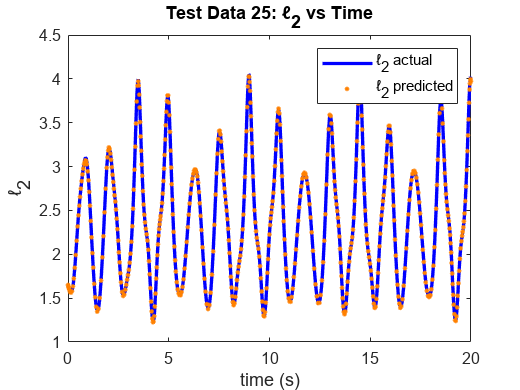

% Loop through the specified simulations
for i = [16 25]%start:numSimulations
    % Extracting data for the current simulation
    time = data{i, 1};
    theta1 = data{i, 2};
    theta2 = data{i, 3};
    omega1 = data{i, 4};
    omega2 = data{i, 5};
    x1 = data{i, 6};
    y1 = data{i, 7};
    x2 = data{i, 8};
    y2 = data{i, 9};
    

    % Transposing the data
    inputTime   = time';
    inputTheta1 = theta1';
    inputTheta2 = theta2';
    inputOmega1 = omega1';
    inputOmega2 = omega2';
    inputX1     = x1';
    inputY1     = y1';
    inputX2     = x2';
    inputY2     = y2';
    
    % Calculating the Euclidean norm from actual data using theta and omega
    l2_norm_actual = sqrt(data11(i).theta1.^2 + data11(i).theta2.^2 + data11(i).omega1.^2 + data11(i).omega2.^2);


    % Making predictions using the neural network  
    predictedTime   = predict(net, {inputTime});
    predictedTheta1 = predict(net, {inputTheta1});
    predictedTheta2 = predict(net, {inputTheta2});
    predictedOmega1 = predict(net, {inputOmega1});
    predictedOmega2 = predict(net, {inputOmega2});
    predictedX1     = predict(net, {inputX1});
    predictedY1     = predict(net, {inputY1});
    predictedX2     = predict(net, {inputX2});
    predictedY2     = predict(net, {inputY2});

    % Converting predicted data to matrices
    newPredictedTime   = cell2mat(predictedTime);
    newPredictedTheta1 = cell2mat(predictedTheta1);
    newPredictedTheta2 = cell2mat(predictedTheta2);
    newPredictedOmega1 = cell2mat(predictedOmega1);
    newPredictedOmega2 = cell2mat(predictedOmega2);
    newPredictedX1     = cell2mat(predictedX1);
    newPredictedY1     = cell2mat(predictedY1);
    newPredictedX2     = cell2mat(predictedX2);
    newPredictedY2     = cell2mat(predictedY2);
    
    % Calculating the Euclidean norm from predicted data using theta and omega
    l2_norm_predicted = sqrt(newPredictedTheta1.^2 + newPredictedTheta2.^2 + newPredictedOmega1.^2 + newPredictedOmega2.^2);
    
    % Plotting actual and predicted Euclidean norm over time
     figure;        
     time = time;
     plot(time, l2_norm_actual,'b', 'LineWidth', 2);
     hold on;
     plot(time, l2_norm_predicted, 'Color', [1, 0.5, 0], 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 8);  
    xlabel('time (s)');
    ylabel('ℓ_{2}');
    title(['Test Data ', num2str(i), ': ℓ_{2} vs Time']);
    legend('ℓ_{2} actual', 'ℓ_{2} predicted'); 
    hold off;  
    
    % Storing the current figure handle
    figHandles{i} = gcf;
end

% Saving all figures into a single MAT-file
save('DP_Euclidean_Norm_figures.mat', 'figHandles');

% To load the figures:
% 1. Loading the MAT-file
loadedData = load('DP_Euclidean_Norm_figures.mat');

% 2. Access the figure handle
loadedFigHandles = loadedData.figHandles;

% 3. Display the figures
for i = [16 25]%start:numSimulations
    figure(loadedFigHandles{i});
end